clc;
clear all;
close all;
tic

Load data from config file using load_config function

config = load_config('conf_file')


config =

  dictionary (string ⟼ cell) with 7 entries:

    "num_Tx"   ⟼ {'4'}
    "num_Rx"   ⟼ {'4'}
    "M"        ⟼ {'16'}
    "num_symb" ⟼ {'50000'}
    "points"   ⟼ {'20'}
    "ebn0_min" ⟼ {'8'}
    "ebn0_max" ⟼ {'18'}



Example of printing 

% config{'num_Tx'}

Write on file the number of tx antennas

% fileId = fopen('output.txt', 'w');
% fprintf(fileId, '%s\n', config{'num_symb'})
% fclose(fileId)

Print what's inside the output file

% type output.txt

## **Inizio parte effettiva**

Preparazione variabili

num_Tx = str2num(config{'num_Tx'})

num_Tx = 4

num_Rx = str2num(config{'num_Rx'})

num_Rx = 4

eb_n0_min = str2num(config{'ebn0_min'})

eb_n0_min = 8

eb_n0_max = str2num(config{'ebn0_max'})

eb_n0_max = 18

points = str2num(config{'points'})

points = 20

mod_Order = str2num(config{'M'})

mod_Order = 16

num_symbols = str2num(config{'num_symb'})

num_symbols = 50000


eb_n0 = linspace(eb_n0_min, eb_n0_max, points);

Old communication system:

% generate random symbols
symbols = randi([0 mod_Order-1], 1, num_symbols);

% array of ones with length equal to number of tx antennas
deltas = ones(1, num_Tx);
% number of symbols transmitte
num_symbols = length(symbols);
%length of eb_n0 vector
lenEbN0 = length(eb_n0);

%% Modulation
% modulate input signal x using QAM with specified modulation order M
xmod = qammod(symbols, mod_Order);

% reshape xmod into a matrix with number of rows equal to number of tx antennas and 
% number of columns equal to number of symbols/number of tx antennas
xmod=reshape(xmod, num_Tx, num_symbols/num_Tx);

% Kronecker tensor product of xmod and deltas
xmod=kron(xmod,deltas);

% % Rayleigh channel
% initialize the matrix h to represent Rayleigh channel fading
% each row of h represents a fading channel between a tx antenna and a rx antenna
% generate a random channel for each fading channel using normal distribution
h = (1/sqrt(2)) * (randn(num_Tx * num_Rx, num_symbols/num_Rx) + 1i * randn(num_Tx * num_Rx, num_symbols/num_Rx));

% reshape h into a matrix with number of rows equal to number of tx antennas and number of columns equal to number of symbols
H = reshape(h, num_Tx, num_symbols);

% calculate the dot product of H and xmod and sum on the columns
tmp = sum(H .* xmod,1);

% reshape the result into a matrix with number of rows equal to number of rx antennas and number of columns equal to number of symbols/number of rx antennas
y = reshape(tmp, num_Rx, num_symbols/num_Rx);

% reshape h into a 3D matrix with dimensions equal to number of tx antennas, number of rx antennas, and number of symbols/number of rx antennas
H=reshape(h,num_Tx, num_Rx, num_symbols/num_Rx);

% define BER null vector for V-BLAST and ZF
ber_vblast = zeros(1,lenEbN0);
ber_zf = zeros(1,lenEbN0);
ber_mmse = zeros(1,lenEbN0);

%% Receiver
    for k=1:lenEbN0 % loop through each Eb/N0 value
        % generate noise signal
        N1 = 1 / sqrt(2) * (randn(1,num_symbols)+1i * randn(1,num_symbols)); 
        % reshape the noise signal
        N1 = reshape(N1, num_Rx, num_symbols/num_Rx); 
         
        % add noise to received signal
        % Calculate the noise power
        noisePower = 1 / (2 * log2(mod_Order)) * 10^(-eb_n0(k) / 10);
        % add noise to received signal
        ynoisy = y + sqrt(noisePower) * N1;
        
        % reshape the received signal with noise
        ynoisy = reshape(ynoisy,num_Rx,1,num_symbols/num_Rx); 
        
        % --------------------- VBLAST --------------------- %     
        y_final_vblast = vblast(num_symbols, num_Rx, H, ynoisy, mod_Order);
        y_final_vblast = reshape(y_final_vblast, 1, []); 
        
        % Calculate the symbol error rate
        [~, tmp_ser_vb]=symerr(symbols,y_final_vblast);         
        % Convert to bit error rate
        ber_vblast(k)=tmp_ser_vb/log2(mod_Order);     
        % -------------------------------------------------- %
                
        % ----------------------- ZF ----------------------- %
        % Compute received signal matrix using zero_forcing function
        rcvd_zf = zero_forcing(num_symbols, num_Rx, H, ynoisy);
        % Demodulate the received signal
        y_final_zf = qamdemod(reshape(rcvd_zf, 1, num_symbols), mod_Order);
        % Calculate the symbol error rate
        [~, tmp_ser_zf] = symerr(symbols, y_final_zf);        
        % Convert to bit error rate
        ber_zf(k) = tmp_ser_zf / log2(mod_Order);
        % -------------------------------------------------- %

        % ---------------------- MMSE ---------------------- %
        % rcvd_mmse = mmse(config{'num_symb'}, num_Rx, H, ynoisy);
        % % Demodulate the received signal
        % y_final_mmse = qamdemod(reshape(rcvd_mmse, 1, num_symbols), mod_Order);
        % % Calculate the symbol error rate
        % [~, tmp_ser_mmse] = symerr(symbols, y_final_mmse);        
        % % Convert to bit error rate
        % ber_mmse(k) = tmp_ser_mmse / log2(mod_Order);

        % -------------------------------------------------- %
    end

Elapsed time is 162.582538 seconds.


Output dei risultati:

ber_zf

ber_zf =     0.0029    0.0025    0.0022    0.0023    0.0019    0.0016    0.0015    0.0013    0.0010    0.0010    0.0009    0.0008    0.0006    0.0006    0.0004    0.0005    0.0004    0.0003    0.0002    0.0003


ber_vblast

ber_vblast = 1.0e-03 *

    0.6650    0.6550    0.5150    0.4800    0.2750    0.3450    0.3450    0.2450    0.2400    0.2400    0.2000    0.2000    0.0950    0.1100    0.0750    0.0800    0.0750    0.0700    0.0200    0.0300


Salva i risultati su file

fileId = fopen('output.txt', 'w');
fprintf(fileId, '%s\n', ber_zf)

ans = 260

% fprintf(fileId, '%s\n', ber_vblast)
fclose(fileId)

ans = 0

Stampa il contenuto del file

type output.txt

2.905000e-03
2.455000e-03
2.215000e-03
2.325000e-03
1.860000e-03
1.575000e-03
1.545000e-03
1.345000e-03
1.020000e-03
9.900000e-04
8.550000e-04
8.050000e-04
5.850000e-04
6.250000e-04
4.300000e-04
5.050000e-04
3.850000e-04
3.150000e-04
2.350000e-04
3.050000e-04


## Leggi il contenuto del file output e plotta i risultati

fileId = fopen('output.txt', 'r');
formatSpec = '%f';
ber = fscanf(fileId, formatSpec);
fclose(fileId);

fig22 = figure;
semilogy(eb_n0,ber','g-o');
hold on
semilogy(eb_n0,ber_vblast,'b-o');
hold off
title({ strcat('BER for: ', num2str(num_Tx), 'x' , num2str(num_Rx), ' Antennas')})
legend('V-Blast','Zero-Forcing', 'MMSE');

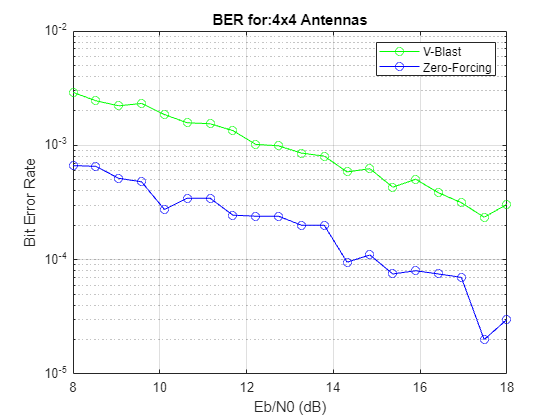

xlabel('Eb/N0 (dB)');
ylabel('Bit Error Rate');
grid on

Print time required: 

toc

Elapsed time is 163.454004 seconds.
